## Problem 10:

There is a process in DSP called an “N-point running sum” (a kind of digital lowpass filter, actually) that is described by the following equation:


$$y\left(n\right)=\sum_{p=0}^{N-1} x\left(n-p\right)$$


Write out, giving the indices of all the x() terms, the algebraic expression that describes the computations needed to compute y(9) when N=6. 

**ANSWER:**

y(9) = x(9-0) + x(9-1) + x(9-1) + x(9-2) + x(9-3) + x(9-4) + x(9-5)

y(9) = 9x + 8x + 7x + 6x + 5x + 4x

y(9) = 39x

## Problem 11:

A 5-point moving averager can be described by the following difference equation:

 (P1-1)

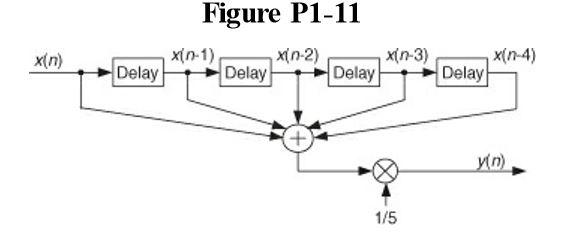

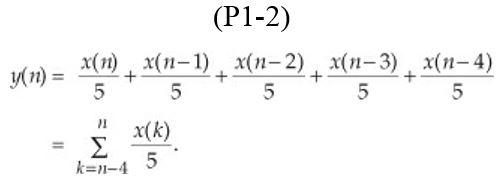

(a) Draw the block diagram of the discrete system described by Eq. (P1-2). 

**ANSWER:**

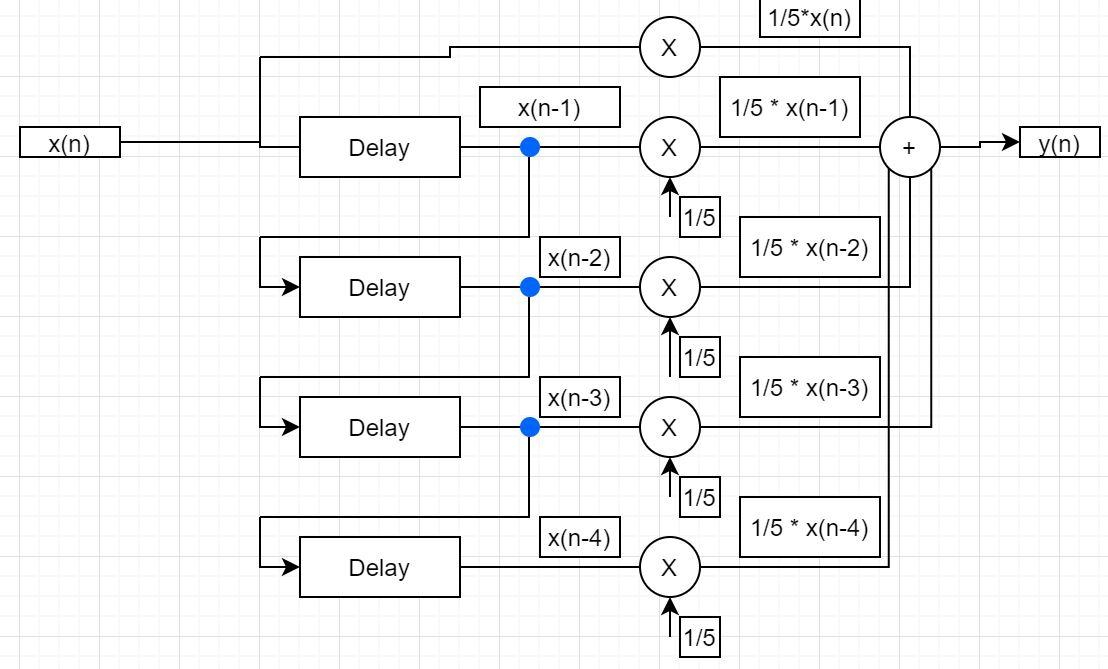

(b) The moving average processes described by Eqs. (P1-1) and (P1-2) have identical impulse responses. Draw that impulse response. 

**ANSWER:**

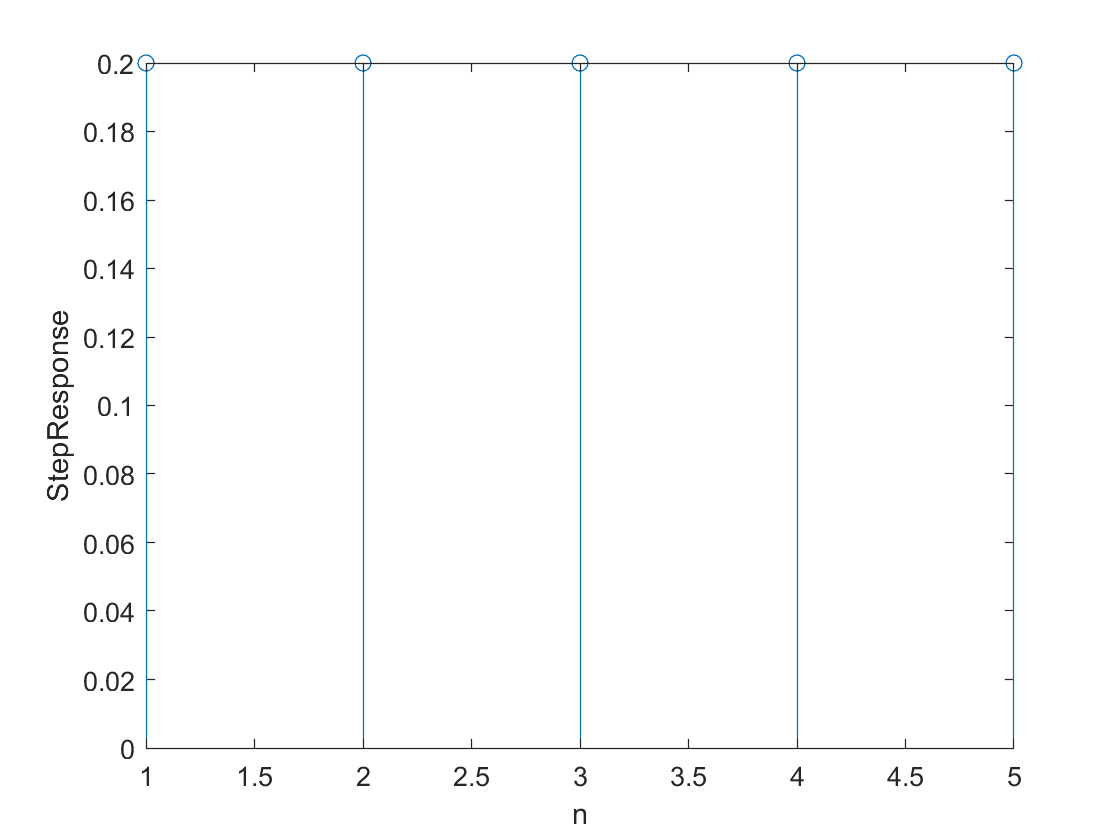

h = [1/5, 1/5, 1/5, 1/5, 1/5];
stem(h)
xlabel('n')
ylabel('StepResponse')

(c) If you had to implement (using programmable hardware or assembling discrete hardware components) either Eq. (P1-1) or Eq. (P1-2), which would you choose? Explain why. 

**ANSWER:**

If I had to choose an equation to implement it would be Eq. (P1-1). This equation is much simpler because it has one attenuator and 4 delays elements while Eq. (P1-2) needs 5 attenuators and 4 delays.

## Problem 13:

 Let’s say you are writing software code to generate an x(n) test sequence composed of the sum of two equal-amplitude discrete cosine waves, as


$$x\left(n\right)=\mathrm{cos}\left(2\pi f_O nt_s +\phi \right)+\mathrm{cos}\left(2\pi f_O nt_s \right)$$


where ts is the time between your x(n) samples, and ϕ is a constant phase shift measured in radians. An example x(n) when ϕ = π/2 is shown in Figure P1-13 where the x(n) sequence, represented by the circular dots, is a single sinusoid whose frequency is fo Hz

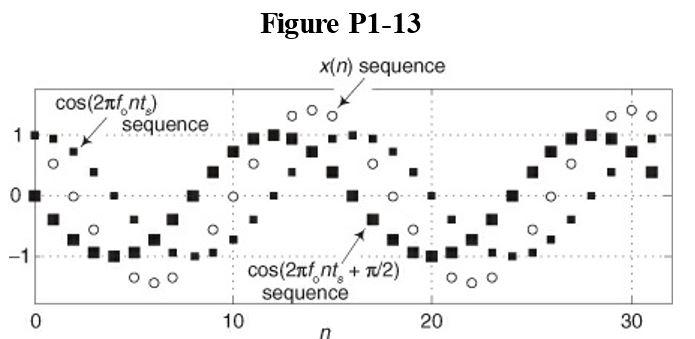

Using the trigonometric identity cos(α+β) + cos(α−β) = 2cos(α)cos(β), derive an equation for x(n) that is of the form 


$$x\left(n\right)=2\mathrm{cos}\left(\alpha \right)\mathrm{cos}\left(\beta \right)$$


where variables α and β are in terms of 2πfonts and ϕ. 

**ANSWER:**

cosα(cosβ + 1) - sinαsinβ

## Problem 15:

Considering two continuous (analog) sinusoids, having initial phase angles of α radians at time t = 0, replace the following “?” characters with the correct angle arguments: 

(a) sin(2πfot + α) = cos(?). 

**ANSWER:**

sin(2πfot + α) = cos(π/2-(2πfot+α))

(b) cos(2πfot + α) = sin(?). 

**ANSWER:**

cos(2πfot + α) = sin(π/2+α+2πfot)

## Problem 16:

 National Instruments Corp. manufactures an A/D converter, Model #NI USB-5133, that is capable of sampling an analog signal at an fs sample rate of 100 megasamples per second (100 MHz). The A/D converter has internal memory that can store up to 4×106 discrete samples. What is the maximum number of cycles of a 25 MHz analog sinewave that can be stored in the A/D converter’s memory? Show your work. 

**ANSWER:**

Sampling rate = 100MHz = $100*{10}^{-6}$ sample/second

Sinewave Frequency = 25 MHz = 25 $*\;{10}^{-6}$

Num of Sample per cycle = 100/25 = 4

Memory = 4 * ${10}^{-6}$

Num of Cycle that can be stores = Memory / (Num of sample per cycle) 

=  $4*\frac{{10}^6 }{4}={10}^6 \;\mathrm{cycles}$

## Problem 17:

In the first part of the text’s Section 1.5 we stated that for a process (or system) to be linear it must satisfy a scaling property that we called the proportionality characteristic in the text’s Eq. (114). Determine if the following processes have that proportionality characteristic: 

(a) ya(n) = x(n−1)/6, 

**ANSWER:**

Yes

(b) yb(n) = 3 + x(n), 

**ANSWER:**

No

(c) yc(n) = sin[x(n)]. 

**ANSWER:**

Yes

This problem is not “busy work.” Knowing if a process (or system) is linear tells us what signal processing principles, and algorithms, can be applied in the analysis of that process (or system). 